# Varying speed, varying path

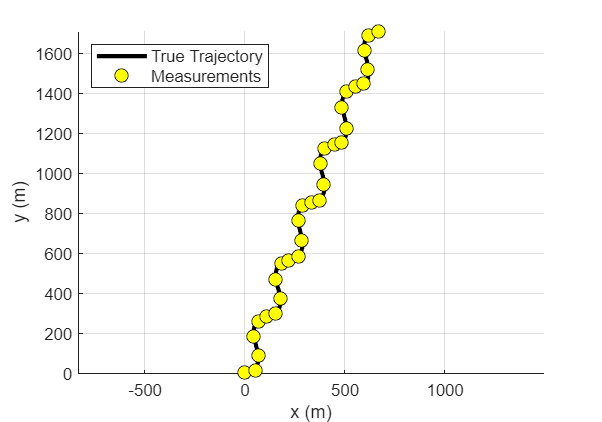

%% EKF-based Trajectory Prediction with Uncertainty Funnel
% Sinusoidal heading with varying speed

clear; clc; close all;

%% Scenario Parameters
Tf          = 300;        % total duration [s]
dt_truth    = 0.5;        % truth integration step [s]
dt_filter   = 1;        % filter propagation step [s]
T_meas      = 10;       % measurement interval [s]
T_pred      = 60;       % prediction horizon [s]

% Initial conditions
x0_true   = 0;             % m
y0_true   = 0;             % m
v0_true   = 4.12;           % m/s
psi0_true = deg2rad(10);   % rad

% Heading modulation (sinusoidal turn-rate)
Omega_amp = deg2rad(6);    % rad/s peak turn-rate
f_turn    = 0.02;          % Hz

% Speed modulation (sinusoidal acceleration)
A_acc     = 0.3877;          % m/s^2 amplitude
f_acc     = 0.02;          % Hz

acc_fun   = @(t) A_acc   * sin(2*pi*f_acc*t);
omega_fun = @(t) Omega_amp * sin(2*pi*f_turn*t);

% Measurement noise
sigma_xy  = 3;           % m
sigma_th  = deg2rad(2);  % rad

% Process noise
sigma_v     = 0.06;          % m/s
sigma_psi   = deg2rad(0.3);  % rad
sigma_omega = deg2rad(0.12); % rad/s
sigma_a     = 0.08;          % m/s^2

rng(5);
n_sigma = 2; 
wrapAng = @(a) atan2(sin(a), cos(a));

%% Truth Trajectory
t_truth = 0:dt_truth:Tf;
N_truth = numel(t_truth);
X_true = zeros(6, N_truth);
X_true(:,1) = [x0_true; y0_true; v0_true; psi0_true; omega_fun(0); acc_fun(0)];

for k = 2:N_truth
    t  = t_truth(k-1);
    dt = dt_truth;

    nsub = 5; dts = dt/nsub;
    x = X_true(:,k-1);
    for s = 1:nsub
        v   = x(3);
        psi = x(4);
        omg = omega_fun(t + (s-1)*dts);
        a   = acc_fun(  t + (s-1)*dts);

        x(1) = x(1) + v*cos(psi)*dts;
        x(2) = x(2) + v*sin(psi)*dts;
        x(3) = max(0, v + a*dts);
        x(4) = wrapAng(psi + omg*dts);
        x(5) = omg;
        x(6) = a;
    end
    X_true(:,k) = x;
end

%% Measurements
t_meas = 0:T_meas:Tf;  N_meas = numel(t_meas);
z_meas = zeros(3, N_meas);
idx_meas_truth = round(t_meas/dt_truth)+1;

for i = 1:N_meas
    kk = idx_meas_truth(i);
    x = X_true(:,kk);
    z_meas(:,i) = [ x(1) + sigma_xy*randn;
                    x(2) + sigma_xy*randn;
                    wrapAng(x(4) + sigma_th*randn) ];
end

%% EKF Model
prop = @(x,dt) propagate_ncct_va(x, dt);
Fnum = @(x,dt) numJacobian(@(xx) prop(xx,dt), x);

h    = @(x) [x(1); x(2); wrapAng(x(4))];
H    = @(x) [1 0 0 0 0 0;
             0 1 0 0 0 0;
             0 0 0 1 0 0];
R    = diag([sigma_xy^2, sigma_xy^2, sigma_th^2]);

Q_from_dt = @(dt) diag([ ...
    (0.5*max(v0_true,1)*dt)^2, ...
    (0.5*max(v0_true,1)*dt)^2, ...
    (sigma_v*sqrt(dt))^2, ...
    (sigma_psi*sqrt(dt))^2, ...
    (sigma_omega*sqrt(dt))^2, ...
    (sigma_a*sqrt(dt))^2 ]);

%% EKF Initialisation 
p1 = z_meas(1:2,1); th1 = z_meas(3,1);
p2 = z_meas(1:2,2); th2 = z_meas(3,2);
p3 = z_meas(1:2,3); th3 = z_meas(3,3);

dt12 = t_meas(2) - t_meas(1);
dt23 = t_meas(3) - t_meas(2);

v12     = norm(p2 - p1)/max(dt12,1e-6);
v23     = norm(p3 - p2)/max(dt23,1e-6);
a_init  = (v23 - v12)/max(dt23,1e-6);
psi_init   = th2;
omega_init = wrapAng(th3 - th2)/max(dt23,1e-6);

xhat = [p2(1); p2(2); max(v12,0.1); psi_init; omega_init; a_init];
Phat = diag([ (4*sigma_xy)^2, (4*sigma_xy)^2, ...
              (max(v12,0.5))^2, deg2rad(10)^2, (deg2rad(2)/max(dt23,1))^2, 0.25^2 ]);

%% Run EKF & Compute Uncertainty
t_filter = 0:dt_filter:Tf; N_filt = numel(t_filter);
X_filt   = nan(6, N_filt);

predictions = cell(N_meas,1);
uncertainty_bounds = cell(N_meas,1);

meas_ptr = 1;
for k = 1:N_filt
    t_now = t_filter(k);

    % Predict
    Fk  = Fnum(xhat, dt_filter);
    Qk  = Q_from_dt(dt_filter);
    xhat = prop(xhat, dt_filter);
    Phat = Fk*Phat*Fk' + Qk;
    X_filt(:,k) = xhat;

    % Update on measurement times
    if meas_ptr <= N_meas && abs(t_now - t_meas(meas_ptr)) < 1e-9
        z = z_meas(:,meas_ptr);
        zhat = h(xhat);

        innov = z - zhat; innov(3) = wrapAng(innov(3));
        Hk = H(xhat); S = Hk*Phat*Hk' + R; K = Phat*Hk'/S;

        xhat = xhat + K*innov;
        Phat = (eye(6) - K*Hk)*Phat;

        % Roll out prediction with covariance
        Np = round(T_pred/dt_filter);
        future = zeros(6, Np+1);
        P_history = zeros(6, 6, Np+1);
        future(:,1) = xhat;
        P_history(:,:,1) = Phat;
        
        xpr = xhat; Ppr = Phat;
        for j = 2:Np+1
            Fp = Fnum(xpr, dt_filter);
            Qp = Q_from_dt(dt_filter);
            xpr = prop(xpr, dt_filter);
            Ppr = Fp*Ppr*Fp' + Qp;
            future(:,j) = xpr;
            P_history(:,:,j) = Ppr;
        end

        predictions{meas_ptr} = struct('t0',t_now,'dt',dt_filter,'states',future);
        uncertainty_bounds{meas_ptr} = struct('positions', future(1:2,:), ...
                                               'P_history', P_history, ...
                                               'n_sigma', n_sigma);
        meas_ptr = meas_ptr + 1;
    end
end

%% Plot 1: True Trajectory & Measurements
figure('Color','w','Position',[100 100 1000 700]);
hold on; grid on; axis equal;
xlabel('x (m)'); ylabel('y (m)');

plot(X_true(1,:), X_true(2,:), 'k-', 'LineWidth', 2.5, 'DisplayName', 'True Trajectory');
plot(z_meas(1,:), z_meas(2,:), 'ko', 'MarkerSize', 8, ...
     'MarkerFaceColor', 'y', 'DisplayName', 'Measurements');

legend('Location', 'northwest', 'FontSize', 10);

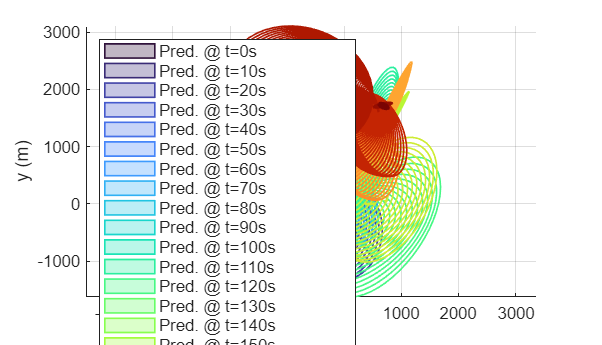


%% Plot 2: Uncertainty Funnels
figure('Color','w','Position',[150 150 1400 800]);
hold on; grid on; axis equal;
xlabel('x (m)'); ylabel('y (m)');

n_updates = length(predictions);
colors = turbo(n_updates);

for i = 1:n_updates
    if isempty(predictions{i}), continue; end
    
    pred_pos = predictions{i}.states(1:2,:);
    unc = uncertainty_bounds{i};
    P_hist = unc.P_history;
    n_steps = size(pred_pos, 2);
    
    ellipse_x = [];
    ellipse_y = [];
    
    for j = 1:n_steps
        P_pos = P_hist(1:2, 1:2, j);
        pos = pred_pos(:, j);
        
        [V, D] = eig(P_pos);
        theta_ellipse = linspace(0, 2*pi, 50);
        ellipse_pts = unc.n_sigma * sqrtm(D) * [cos(theta_ellipse); sin(theta_ellipse)];
        ellipse_pts = V * ellipse_pts;
        
        ellipse_x = [ellipse_x, pos(1) + ellipse_pts(1,:), NaN];
        ellipse_y = [ellipse_y, pos(2) + ellipse_pts(2,:), NaN];
    end
    
    if i == n_updates
        lw = 2;
        alpha = 0.6;
        lbl = sprintf('Final Prediction @ t=%.0fs', predictions{i}.t0);
    else
        lw = 1;
        alpha = 0.3;
        lbl = sprintf('Pred. @ t=%.0fs', predictions{i}.t0);
    end
    
    patch(ellipse_x, ellipse_y, colors(i,:), 'FaceAlpha', alpha, ...
          'EdgeColor', colors(i,:), 'LineWidth', lw, 'DisplayName', lbl);
    
    plot(pred_pos(1,:), pred_pos(2,:), '--', 'Color', colors(i,:), ...
         'LineWidth', 1.5, 'HandleVisibility', 'off');
end

legend('Location', 'northwest', 'FontSize', 10);


%% Console Stats
fprintf('=== Uncertainty Funnel Analysis - Sinusoidal Turn Rate + Varying Speed ===\n');

=== Uncertainty Funnel Analysis - Sinusoidal Turn Rate + Varying Speed ===


fprintf('Confidence level: %.1f-sigma (%.1f%%)\n', n_sigma, 100*erf(n_sigma/sqrt(2)));

Confidence level: 2.0-sigma (95.4%)


fprintf('Prediction horizon: %.0f s\n', T_pred);

Prediction horizon: 60 s


fprintf('Measurement interval: %.0f s\n', T_meas);

Measurement interval: 10 s


fprintf('\nTrue motion parameters:\n');


True motion parameters:


fprintf('  Initial speed: %.2f m/s\n', v0_true);

  Initial speed: 4.12 m/s


fprintf('  Turn rate amplitude: %.3f deg/s, frequency: %.3f Hz\n', rad2deg(Omega_amp), f_turn);

  Turn rate amplitude: 6.000 deg/s, frequency: 0.020 Hz


fprintf('  Accel amplitude: %.3f m/s², frequency: %.3f Hz\n', A_acc, f_acc);

  Accel amplitude: 0.388 m/s², frequency: 0.020 Hz


fprintf('\nNumber of prediction updates: %d\n', n_updates);


Number of prediction updates: 31



if ~isempty(uncertainty_bounds{end})
    final_unc = uncertainty_bounds{end};
    final_P = final_unc.P_history(:,:,end);
    final_sigma_xy = sqrt(diag(final_P(1:2,1:2)));
    final_total_uncertainty = n_sigma * norm(final_sigma_xy);
    
    fprintf('\nFinal prediction (at t=%.0fs, looking %.0fs ahead):\n', ...
            predictions{end}.t0, T_pred);
    fprintf('  Position uncertainty (%.0fσ): x=±%.2fm, y=±%.2fm\n', ...
        n_sigma, n_sigma*final_sigma_xy(1), n_sigma*final_sigma_xy(2));
    fprintf('  Total uncertainty radius: %.2f m\n', final_total_uncertainty);
    fprintf('  Speed uncertainty (%.0fσ): ±%.3fm/s\n', ...
        n_sigma, n_sigma*sqrt(final_P(3,3)));
    fprintf('  Heading uncertainty (%.0fσ): ±%.2f deg\n', ...
        n_sigma, rad2deg(n_sigma*sqrt(final_P(4,4))));
    fprintf('  Turn rate uncertainty (%.0fσ): ±%.3f deg/s\n', ...
        n_sigma, rad2deg(n_sigma*sqrt(final_P(5,5))));
    fprintf('  Accel uncertainty (%.0fσ): ±%.3f m/s²\n', ...
        n_sigma, n_sigma*sqrt(final_P(6,6)));
    
end


Final prediction (at t=300s, looking 60s ahead):


  Position uncertainty (2σ): x=±77.80m, y=±44.92m


  Total uncertainty radius: 89.84 m


  Speed uncertainty (2σ): ±0.120m/s


  Heading uncertainty (2σ): ±76.19 deg


  Turn rate uncertainty (2σ): ±1.974 deg/s


  Accel uncertainty (2σ): ±1.339 m/s²



%% Helpers
function xnext = propagate_ncct_va(x, dt)
    xn = x;
    nsub = 3; dts = dt/nsub;
    for s = 1:nsub
        v   = xn(3); psi = xn(4); omg = xn(5); a = xn(6);
        xn(1) = xn(1) + v*cos(psi)*dts;
        xn(2) = xn(2) + v*sin(psi)*dts;
        xn(3) = max(0, v + a*dts);
        xn(4) = atan2(sin(psi + omg*dts), cos(psi + omg*dts));
    end
    xnext = xn;
end

function F = numJacobian(f, x)
    n  = numel(x);
    fx = f(x);
    m  = numel(fx);
    F  = zeros(m,n);
    eps = 1e-6;
    for i = 1:n
        dx = zeros(n,1); dx(i) = eps;
        F(:,i) = (f(x+dx) - fx)/eps;
    end
end